%% PROJECT WORK 1- STOCK A6
clear; clc; close all;

csvFile = "btcusd_1-min_data.csv";  
valueCol = "Close";                  
targetPts = 3e4;     

% Load and build timetable
opts = detectImportOptions(csvFile);
T = readtable(csvFile, opts);

% Timestamp -> datetime 
timeRaw = T.Timestamp;
if isnumeric(timeRaw)
    mVal = nanmean(double(timeRaw));
    if mVal > 1e11
        t = datetime(double(timeRaw)/1000, 'ConvertFrom','posixtime', 'TimeZone','UTC');
    else
        t = datetime(double(timeRaw), 'ConvertFrom','posixtime', 'TimeZone','UTC');
    end
else
    t = datetime(string(timeRaw), 'TimeZone','UTC'); 
end

% Select series
assert(ismember(valueCol, string(T.Properties.VariableNames)), ...
    "Column '%s' not found.", valueCol);
y = T.(valueCol);

% cleaned Timetable 
TT = timetable(t, y, 'VariableNames', string(valueCol));
TT = sortrows(TT);
TT = unique(TT);
TT = rmmissing(TT);

fprintf("Observations: %d  |  %s → %s\n", height(TT), datestr(TT.t(1)), datestr(TT.t(end)));

Observations: 7278877  |  01-Jan-2012 10:01:00 → 03-Nov-2025 23:57:00


%% Regolarization of the serie

dt = diff(TT.t);
medStep = median(dt);
isRegular = all(abs(seconds(dt - medStep)) < 1e-9);  

if ~isRegular
    tGrid = (TT.t(1):medStep:TT.t(end)).';
    TTr = retime(TT, tGrid, 'mean');     
else
    TTr = TT;
end

fprintf("Median step: %s | Regular series: %d\n", string(medStep), isRegular);

Median step: 00:01:00 | Regular series: 0


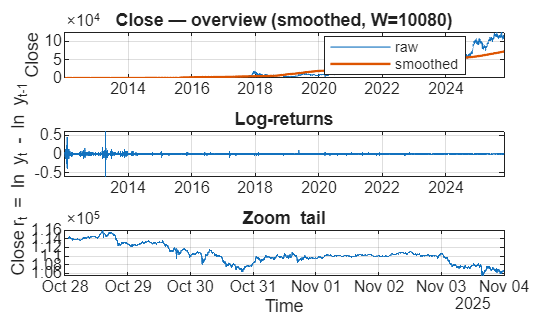

%%  Visualization

TTp = TTr;
if height(TTp) > targetPts
    k = ceil(height(TTp)/targetPts);
    newT = (TTp.t(1):k*medStep:TTp.t(end)).';
    TTp = retime(TTp, newT, 'mean');
end

figure('Name','Exploratory','Color','w');
tiledlayout(3,1,'Padding','compact','TileSpacing','compact');


nexttile;
plot(TTp.t, TTp.(valueCol), '-', 'LineWidth', 0.6); hold on;
W = max(5, round( seconds(days(7)) / seconds(medStep) )); 
ys = movmean(TTp.(valueCol), W, 'omitnan');
plot(TTp.t, ys, '-', 'LineWidth', 1.2);
grid on; box on;
title(sprintf('%s — overview (smoothed, W=%d)', valueCol, W));
ylabel(valueCol); legend('raw','smoothed','Location','best');

% Log-returns 
nexttile;
r = diff(log(TTr.(valueCol)));
plot(TTr.t(2:end), r, '-'); grid on; box on;
title('Log-returns'); ylabel('r_t = ln y_t - ln y_{t-1}');

% (c) Zoom 
nexttile;
tailN = min(10000, max(1000, round(0.1*height(TTr))));
plot(TTr.t(end-tailN+1:end), TTr.(valueCol)(end-tailN+1:end), '-');
grid on; box on; title(sprintf('Zoom  tail'));
xlabel('Time'); ylabel(valueCol);

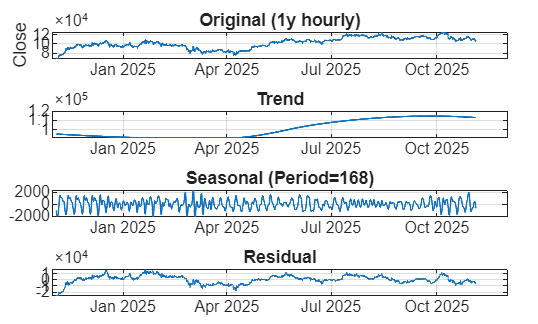

%% Decomposition

TTd = retime(TT, 'regular', 'mean', 'TimeStep', hours(1));

% Last 12 months
tStart = TTd.t(end) - calyears(1);
TTd = TTd(timerange(tStart, TTd.t(end)), :);

% weekly period
Period = 168;

yvec = double(TTd.(valueCol));
yvec = fillmissing(yvec,'linear');
yvec = yvec(:);
N = numel(yvec);
Period = max(2, min(Period, floor(N/2)));

useFallback = false;
if exist('trenddecomp','file') == 2
    try
        [T_tr, S_seas, R_res] = trenddecomp(yvec, 'stl', Period);
    catch
        useFallback = true;
    end
else
    useFallback = true;
end

if useFallback
    Wt = min(max(5*Period, 15), max(N-1, 15));
    T_tr = movmean(yvec, Wt, 'omitnan');

    phase = mod((1:N)'-1, Period) + 1;
    diffs = yvec - T_tr;
    m = accumarray(phase, diffs, [Period,1], @(v) mean(v,'omitnan'), 0);
    S_seas = m(phase);
    S_seas = S_seas - mean(S_seas,'omitnan');
    R_res  = yvec - T_tr - S_seas;
end

figure('Name','Decomposition — hourly (last 12m)','Color','w');
tiledlayout(4,1,'Padding','compact','TileSpacing','compact');
nexttile; plot(TTd.t, yvec, '-', 'LineWidth' , 0.7); grid on; title('Original (1y hourly)'); ylabel(valueCol);
nexttile; plot(TTd.t, T_tr, '-','LineWidth', 1.0); grid on; title('Trend');
nexttile; plot(TTd.t, S_seas, '-', 'LineWidth', 0.8); grid on; title('Seasonal (Period=168)');
nexttile; plot(TTd.t, R_res, '-', 'LineWidth', 0.6); grid on; title('Residual');

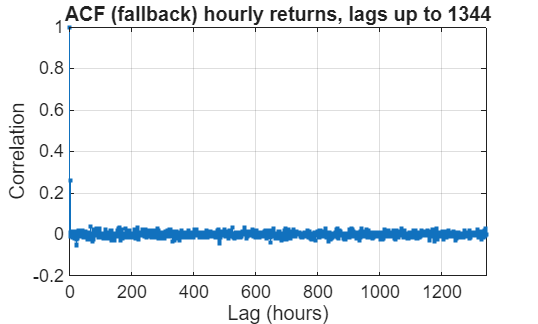

%% ACF
yH = TTd.(valueCol);
yH = fillmissing(yH, 'linear', 'MaxGap', 24, 'EndValues', 'nearest');   
yH = max(yH, eps);                                                     

rH = diff(log(yH));
rH = rH(isfinite(rH));                                              

maxLag = 24*56;                                                      
maxLag = min(maxLag, numel(rH)-1);
if maxLag < 1
    warning('Return serie too short.');
else
    figure('Name','ACF (hourly returns)','Color','w');
    if exist('autocorr','file') == 2
        autocorr(rH, maxLag);
        title(sprintf('ACF of hourly log-returns (NumLags=%d)', maxLag));
        xlabel('Lag (hours)'); ylabel('Autocorrelation');
        grid on;
    else
     
        y0 = rH - mean(rH,'omitnan');
        [c,lags] = xcorr(y0, maxLag, 'coeff');
        keep = lags>=0;
        stem(lags(keep), c(keep), '.'); grid on; box on;
        xlim([0 maxLag]); xlabel('Lag (hours)'); ylabel('Correlation');
        title(sprintf('ACF (fallback) hourly returns, lags up to %d', maxLag));
    end
end

%% Partition
TTP = TTd;               
N = height(TTP);
testFrac = 0.20;

cv = tspartition(N, 'Holdout', testFrac);
idxTrain = training(cv);
idxTest = test(cv);

TT_train = TTP(idxTrain,:);
TT_test = TTP(idxTest,:);

fprintf('\n== Holdout (hourly) ==\n');


== Holdout (hourly) ==


fprintf('Train: %d  [%s → %s]\n', height(TT_train), datestr(TT_train.t(1)), datestr(TT_train.t(end)));

Train: 7008  [03-Nov-2024 23:00:00 → 22-Aug-2025 22:00:00]


fprintf('Test : %d  [%s → %s]\n', height(TT_test), datestr(TT_test.t(1)),  datestr(TT_test.t(end)));

Test : 1752  [22-Aug-2025 23:00:00 → 03-Nov-2025 22:00:00]


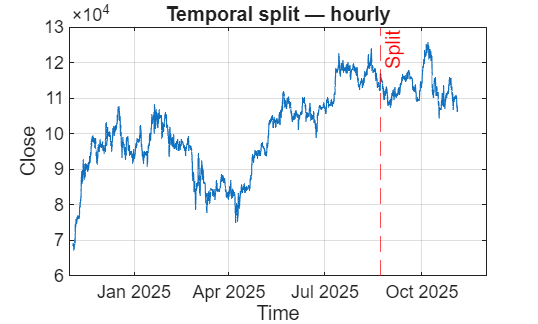


figure('Name','Train/Test Split (hourly)','Color','w');
plot(TTP.t, TTP.(valueCol), '-', 'LineWidth', 0.6); hold on;
xline(TTP.t(find(idxTest,1,'first')-1), '--r', 'Split'); grid on; box on;
title('Temporal split — hourly'); ylabel(valueCol); xlabel('Time');


K = 5;
cvk = tspartition(height(TT_train), "SlidingWindow", K);
